% clear;
data = load('resultadosCSV_magic.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

load('DatosCalibracion.mat');
T           = (1/300e6);

T_buscado = 1/(2*5.123456e6)

T_buscado = 9.7590e-08

T_buscado - 30*T

ans = -2.4096e-09

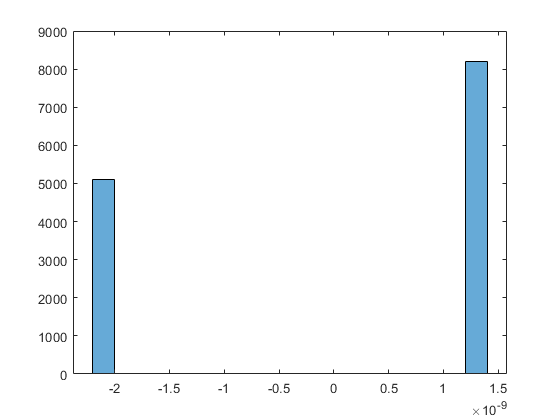

t_fino = cal_start(start) - cal_stop(stop);
histogram(t_fino)

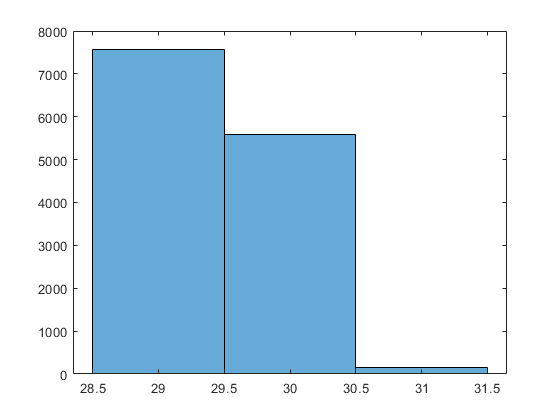

histogram(coarse)

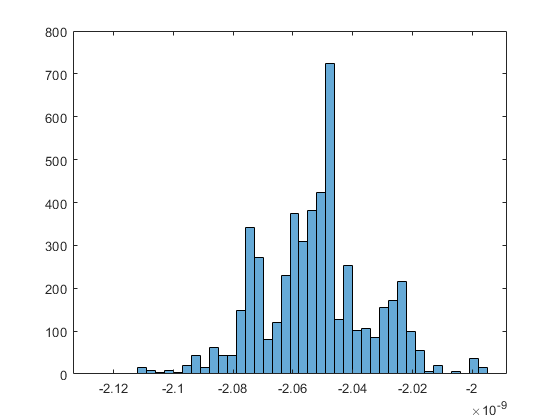


histogram(t_fino(t_fino<0))

T_buscado - (30*T + mean(t_fino(t_fino<0)))

ans = -3.5712e-10

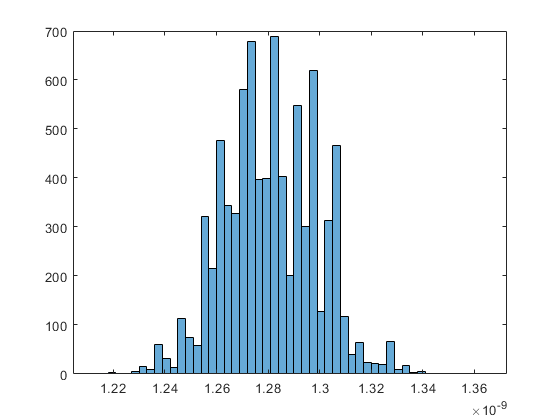


histogram(t_fino(t_fino>0))

T_buscado - (29*T + mean(t_fino(t_fino>0)))

ans = -3.5736e-10


y = [t_fino(t_fino<0), t_fino(t_fino>0)-T]

y = 	1.0e+-8 *

   -0.2054   -0.2058   -0.2050   -0.2021   -0.2047   -0.2024   -0.2048   -0.2055   -0.2060   -0.2047   -0.2066   -0.2054   -0.2043   -0.2055   -0.2063   -0.2049   -0.2041   -0.2016   -0.2063   -0.2073   -0.2073   -0.2048   -0.2017   -0.2059   -0.2028   -0.2053   -0.2068   -0.2073   -0.2076   -0.2082   -0.2058   -0.2081   -0.2056   -0.2047   -0.2060   -0.2048   -0.2055   -0.2025   -0.2071   -0.2075   -0.2018   -0.2074   -0.2047   -0.2031   -0.2049   -0.2057   -0.2073   -0.2022   -0.2073   -0.2073


mean(y)

ans = -2.0524e-09

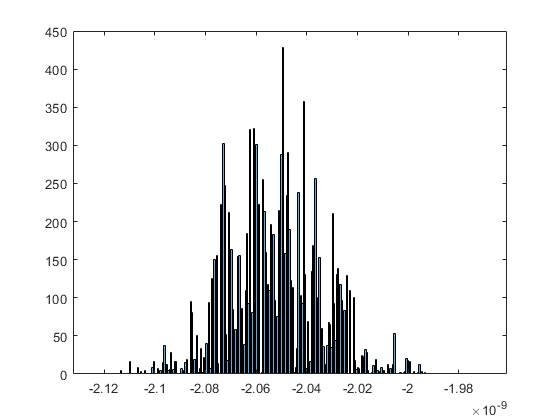

histogram(y, 300)


y = [t_fino(t_fino>0), t_fino(t_fino<0)+T]

y = 	1.0e+-8 *

    0.1293    0.1269    0.1261    0.1268    0.1261    0.1285    0.1298    0.1284    0.1296    0.1300    0.1264    0.1306    0.1304    0.1280    0.1242    0.1279    0.1291    0.1299    0.1286    0.1313    0.1310    0.1317    0.1273    0.1255    0.1265    0.1272    0.1284    0.1264    0.1273    0.1266    0.1287    0.1277    0.1299    0.1286    0.1315    0.1292    0.1280    0.1267    0.1297    0.1286    0.1268    0.1271    0.1307    0.1256    0.1270    0.1262    0.1269    0.1261    0.1268    0.1261


mean(y)

ans = 1.2810e-09

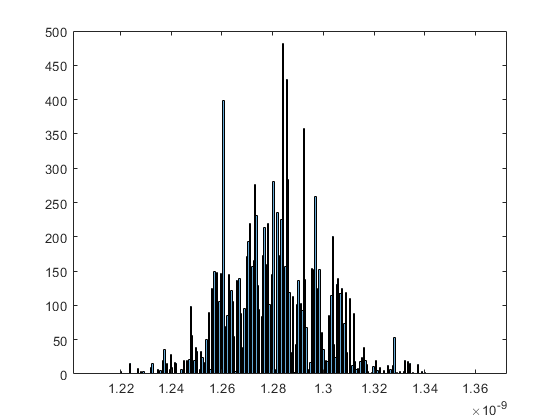

histogram(y, 300)